# k-Wave: time domain simulation of acoustic wave fields

## Chapter 1: Numerical Model

#### Como las ondas se propagan bajo diversas condiciones?

Las ondas acustica genera fluctuaciones dinamias en presion, densidad, temperatura, velocidad de particula, etc. Estos cambios pueden ser mostrados con estas ecuaciones diferenciales de primer grado:

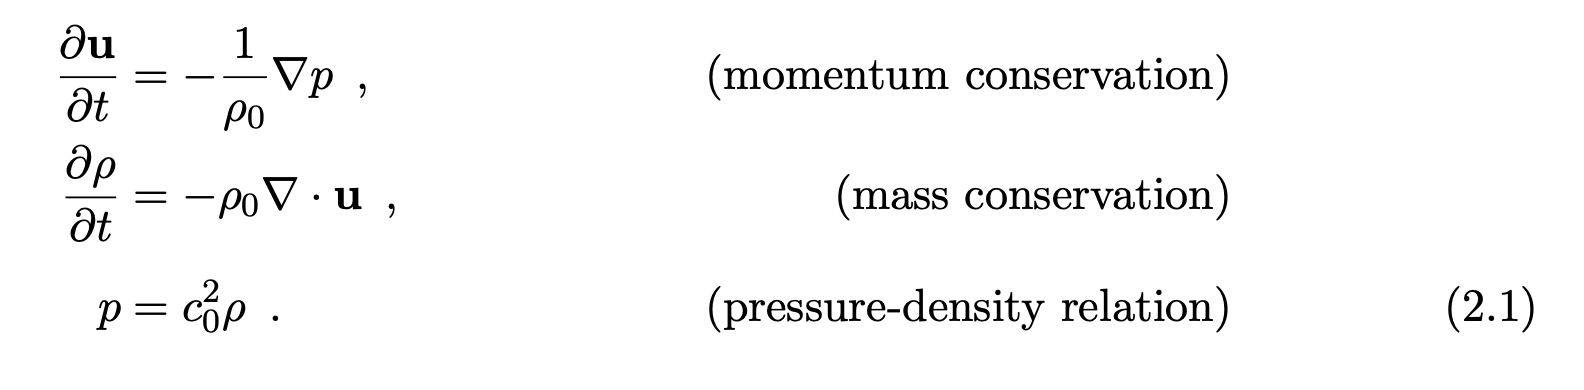

Usualmente en conjunto como ecuacion de onda se foma:

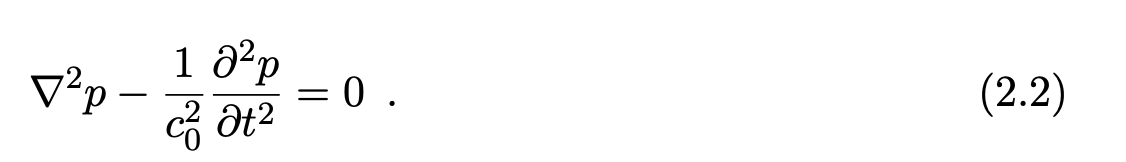

Sin embargo, solo se usan estas funciones en k-Wave, respecto a las tres dimensiones donde se puede calcular: **kspaceFirstOrder1D, kspaceFirstOrder2D, kspaceFirstOrder3D.**

Cuando se incluye **acoustic absortion** y **heterogeneidad:** (L-operator: relacion presion-densidad)  en la propiedad de los materiales, las ecuaciones pueden difereir un poco:

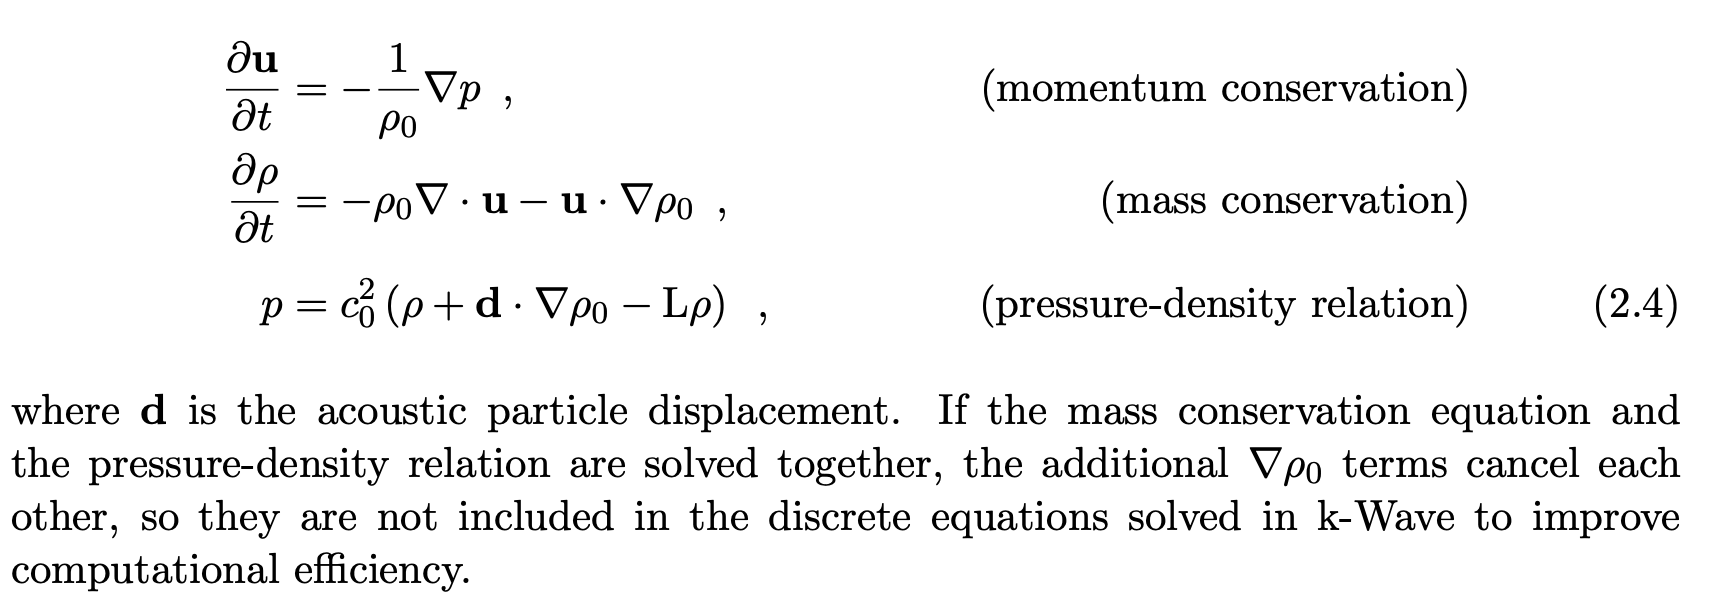

y tambien cuando se anade **no linearidad **cambia (B/A):

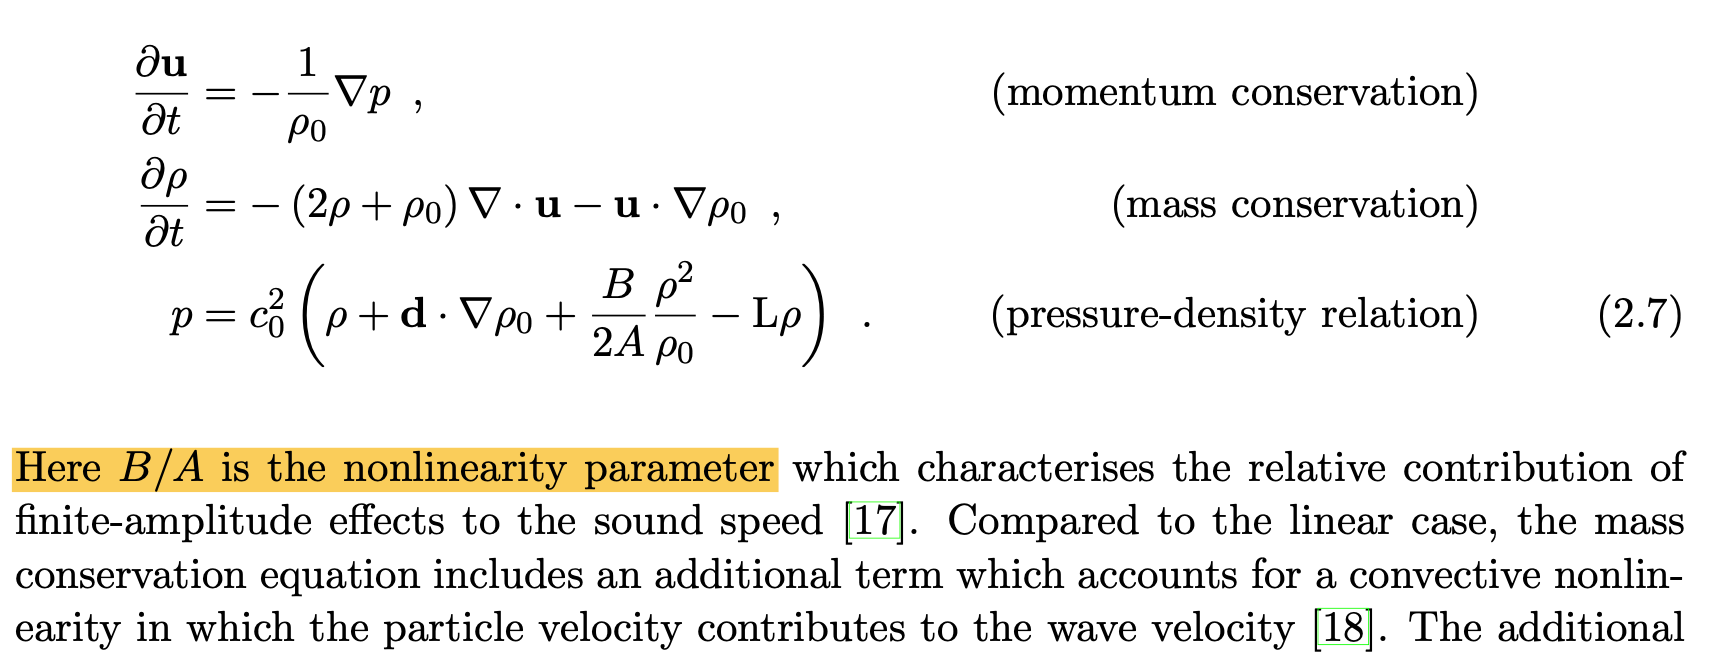

#### Como las ondas son generadas o anadidas al medio?

Aveces** fuentes lineares** pueden ser generadas anadiendo terminos a esas ecuaciones diferenciales:

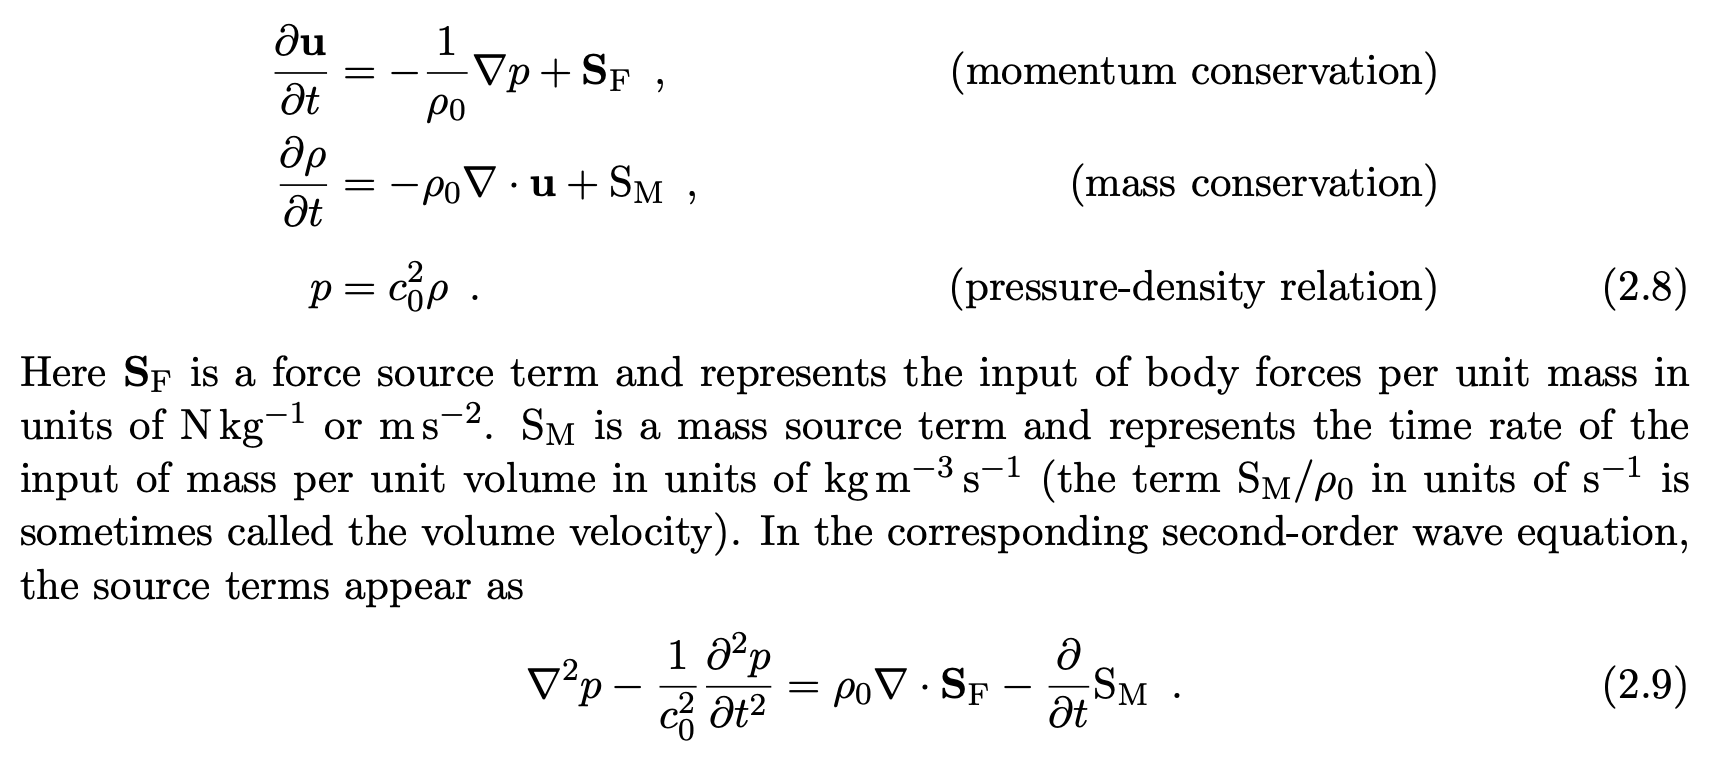

Algunos ejemplos son pistones vibracionales y esferas con oscilasiones radiales, es decir **en general cuerpos cuyo volumen oscilan.**

Tambien relacionado a la ecuacion de la conservacion de la energia, corresponderia a la inyeccion de calor por unidad de volumen y tiempo, por ejemplo por la absorbsion de energia de un un laser modulado:

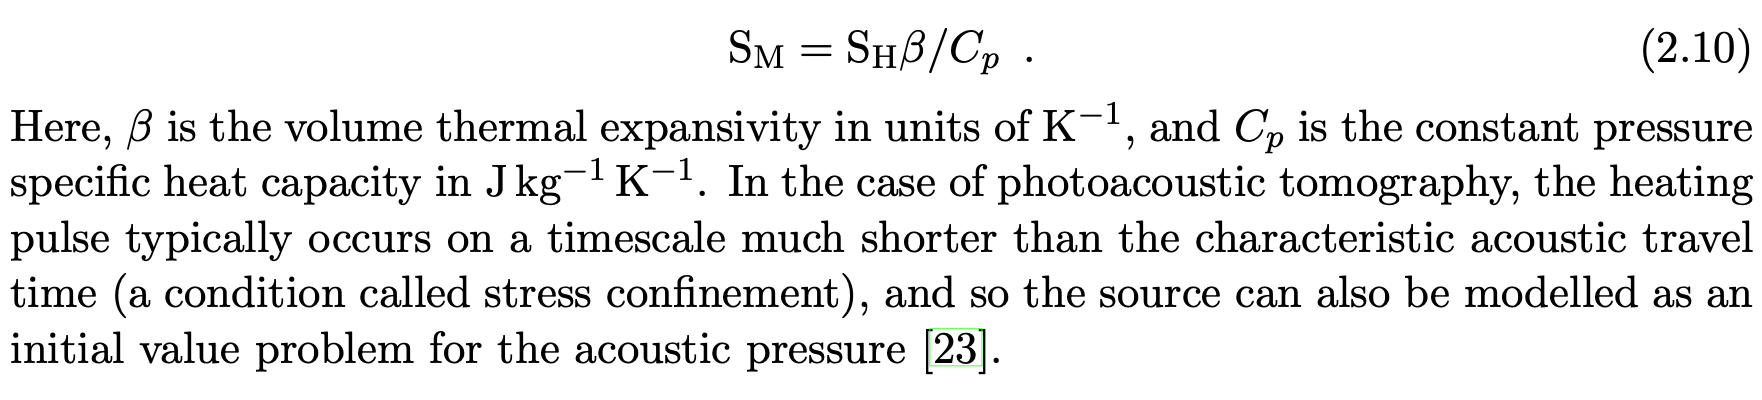

Asimismo existen multiples formas de resolver ecuaciones diferenciales:

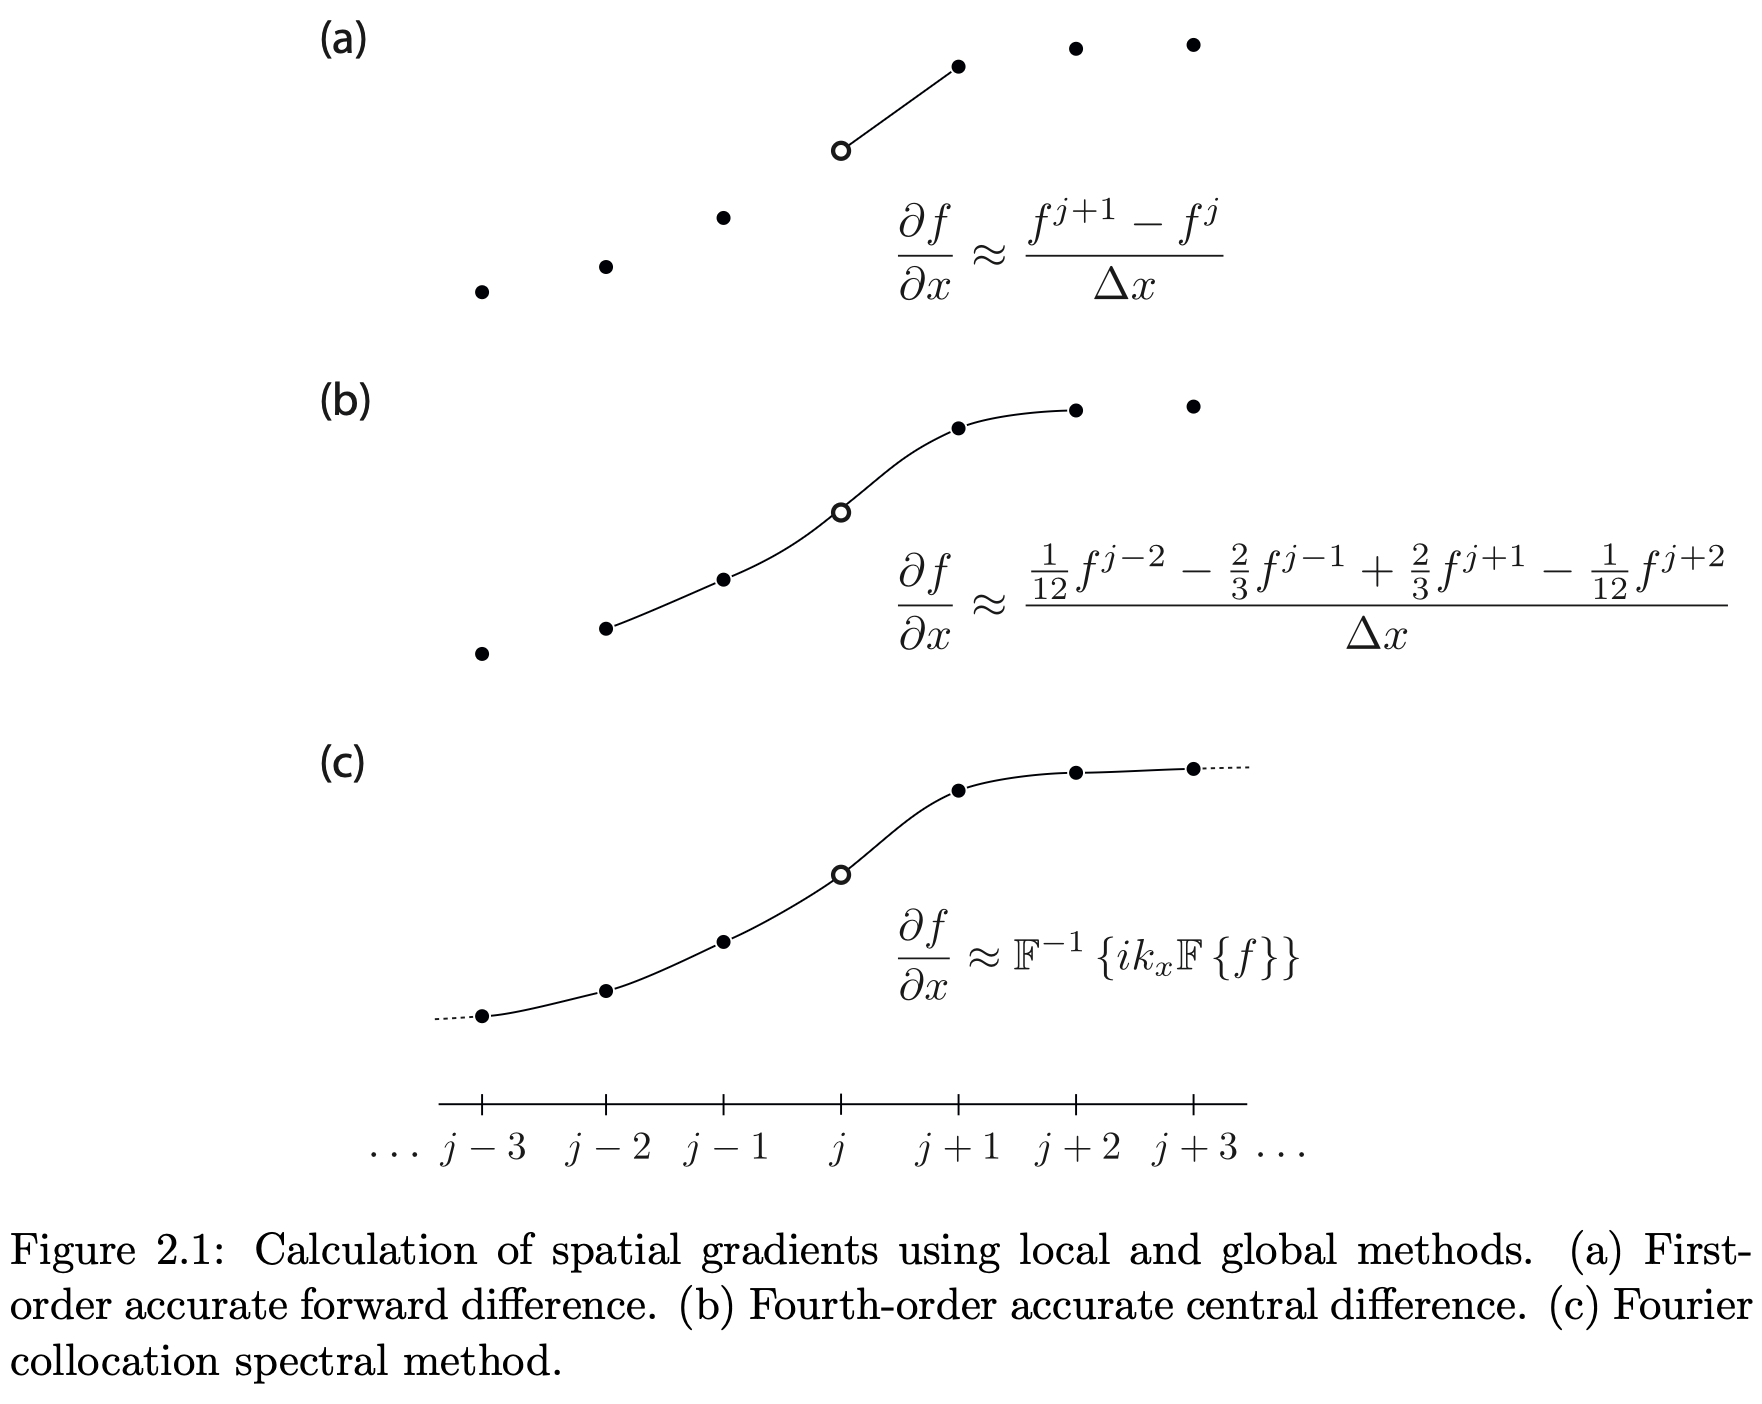

Existen problemas con **classical finite diﬀerence and finite element approaches**, ya que las mallas computacionales para resolver son muy grandes para una computadora normal, ademas de requerir mucho espacio.

En lugar de eso usa** k-space pseudospectral method** que combina spectral calculation of spatial derivatives (un metodo basado en fourier) y temporal propagator:

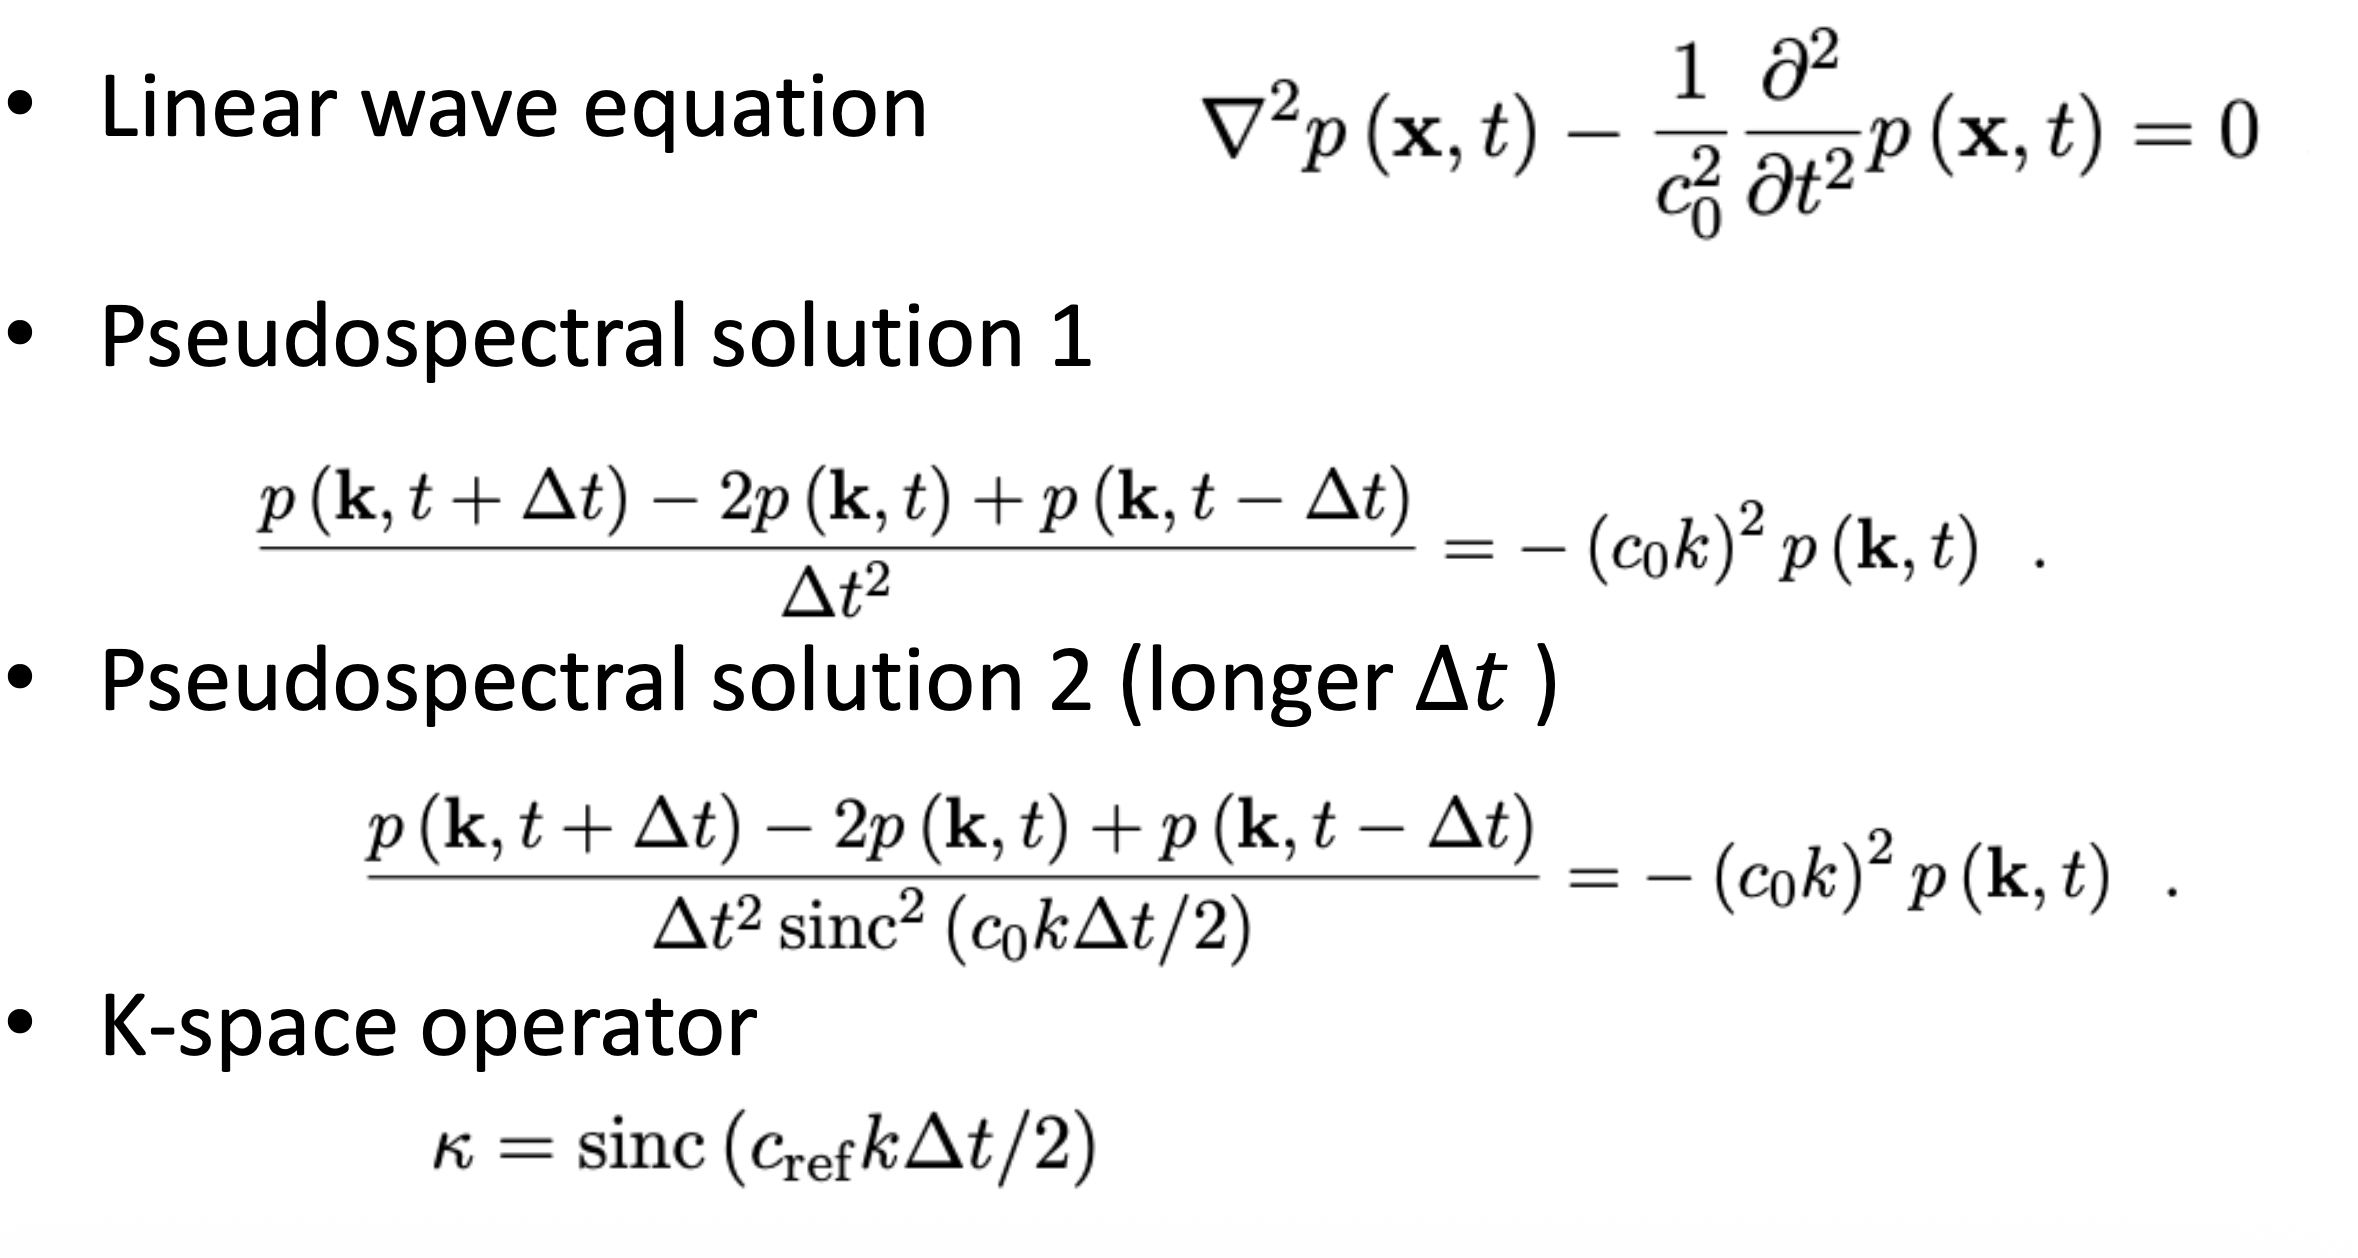

Asimismo tenemos PML significa **Perfectly Matched Layer**. En k-Wave es una **capa absorbente artificial que se coloca en los bordes del dominio de simulación**.

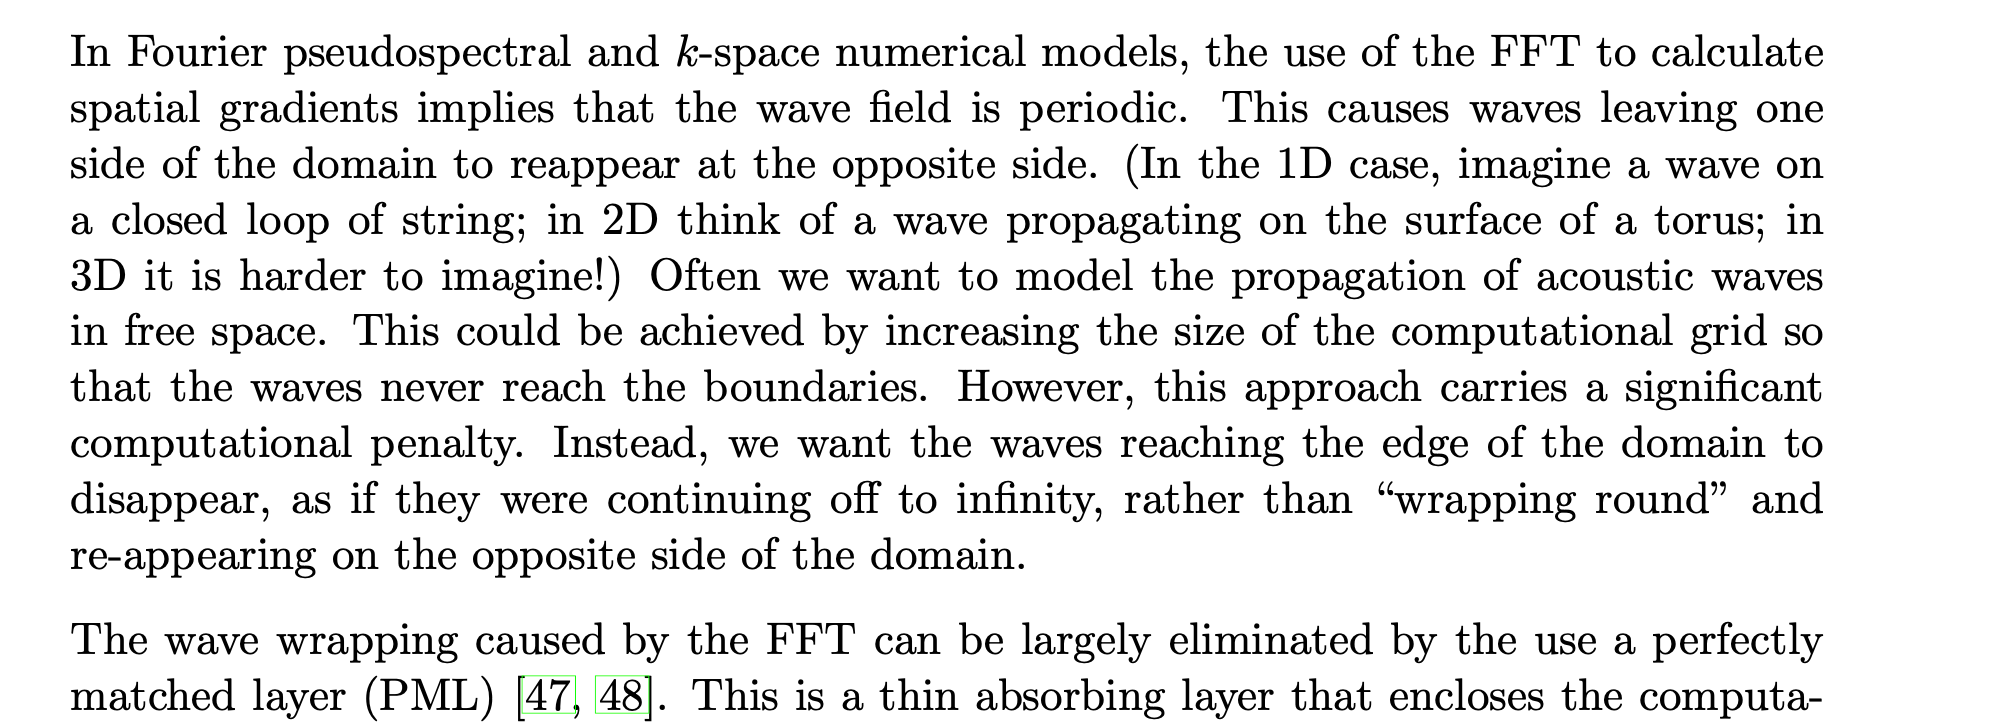

## First-Order Simulation Functions

These are named: **kspaceFirstOrder1D, kspaceFirstOrder2D, and kspaceFirstOrder3D**

The simulation functions are called with four input structures: **kgrid, medium, source and sensor**

The properties of the simulation are then set as fields for these structures in the form **structure.field**

clear;
clc;


%--- Espacio donde se realizara el experimento
% create the computational grid (dominio discretizado y cuanto mide)
Nx = 128; % number of grid points in the x (row) direction
Ny = 256; % number of grid points in the y (column) direction
dx = 50e-6; % grid point spacing in the x direction [m]
dy = 50e-6; % grid point spacing in the y direction [m]

% makeGrid genera internamente las coordenadas 
% espaciales y los números de onda que k-Wave necesita 
% para hacer los cálculos espectrales mediante Fourier.
kgrid = makeGrid(Nx, dx, Ny, dy); % antiguo: makeGrid(Nx, dx, Ny, dy);

         Update codes to use the syntax kgrid = kWaveGrid(...).



%--- Definicion de los medios por el cual se propagara la onda y donde empieza

%dos regiones con diferente velocidad del sonido.
medium.sound_speed = 1500*ones(Nx, Ny); % [m/s] crea matriz 128 × 256 con 1500 m/s
medium.sound_speed(1:50, :) = 1800; % [m/s] 1800
medium.density = 1040; % [kg/m^3]

% define an initial pressure using makeDisc
disc_x_pos = 75; % [grid points]
disc_y_pos = 120; % [grid points]
disc_radius = 8; % [grid points]
disc_mag = 3; % [Pa]

%Perturbación inicial de presión desde la cual empieza a propagarse la onda.
source.p0 = disc_mag*makeDisc(Nx, Ny, disc_x_pos, disc_y_pos, disc_radius);

%--- Donde se encontrarn los sensores y con que distribucion
% define a Cartesian sensor mask of a centered circle with 50 sensor elements
sensor_radius = 2.5e-3; % [m] circunferencia de radio x
num_sensor_points = 50; %sensores

%Se colocan los sensores con su distancia respectiva alrededor del dominio
sensor.mask = makeCartCircle(sensor_radius, num_sensor_points);

%--- Simulacion 
% run the simulation: k-Wave resuelve las ecuaciones
sensor_data_1 = kspaceFirstOrder2D(kgrid, medium, source, sensor,"Smooth", false);

Running k-Wave simulation...
  start time: 24-Aug-2026 15:57:24
  reference sound speed: 1800m/s
  dt: 8.3333ns, t_end: 9.5333us, time steps: 1145
  input grid size: 128 by 256 grid points (6.4 by 12.8mm)
  maximum supported frequency: 15MHz
  calculating Delaunay triangulation...
  precomputation completed in 0.13428s
  starting time loop...
  estimated simulation time 7.6315s...
  simulation completed in 6.1475s
  total computation time 6.2978s


Running k-Wave simulation...
  start time: 24-Aug-2026 15:57:30
  reference sound speed: 1800m/s
  dt: 8.3333ns, t_end: 9.5333us, time steps: 1145
  input grid size: 128 by 256 grid points (6.4 by 12.8mm)
  maximum supported frequency: 15MHz
  smoothing p0 distribution...
  calculating Delaunay triangulation...


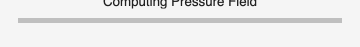

  precomputation completed in 0.097348s
  starting time loop...


Error using  ./ 
Arrays have incompatible sizes for this operation.

Error in kspaceFirstOrder2D (line 915)
        rhox = source.p0 ./ (2 .* c0.^2);
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Related documentation

%Anteriormente el suavizado automatico era 'Smooth' = [true, false, false],
%lo que generaba que source.p0 tenga un tamano incompatible.
sensor_data_2 = kspaceFirstOrder2D(kgrid, medium, source, sensor);

### **Resumen**

Como se observa:

- **kgrid**: define las propiedades de la red donde se computara la simulacion, aqui se determina la cantidad de puntos de red que se usaran para resolver las ecuaciones en este espacio discreto, especificamente con **makeGrid (kWaveGrid actualmente)**.

La siguiente imagen muestra lo que hace las funciones mostradas en el ejemplo de forma resumida:

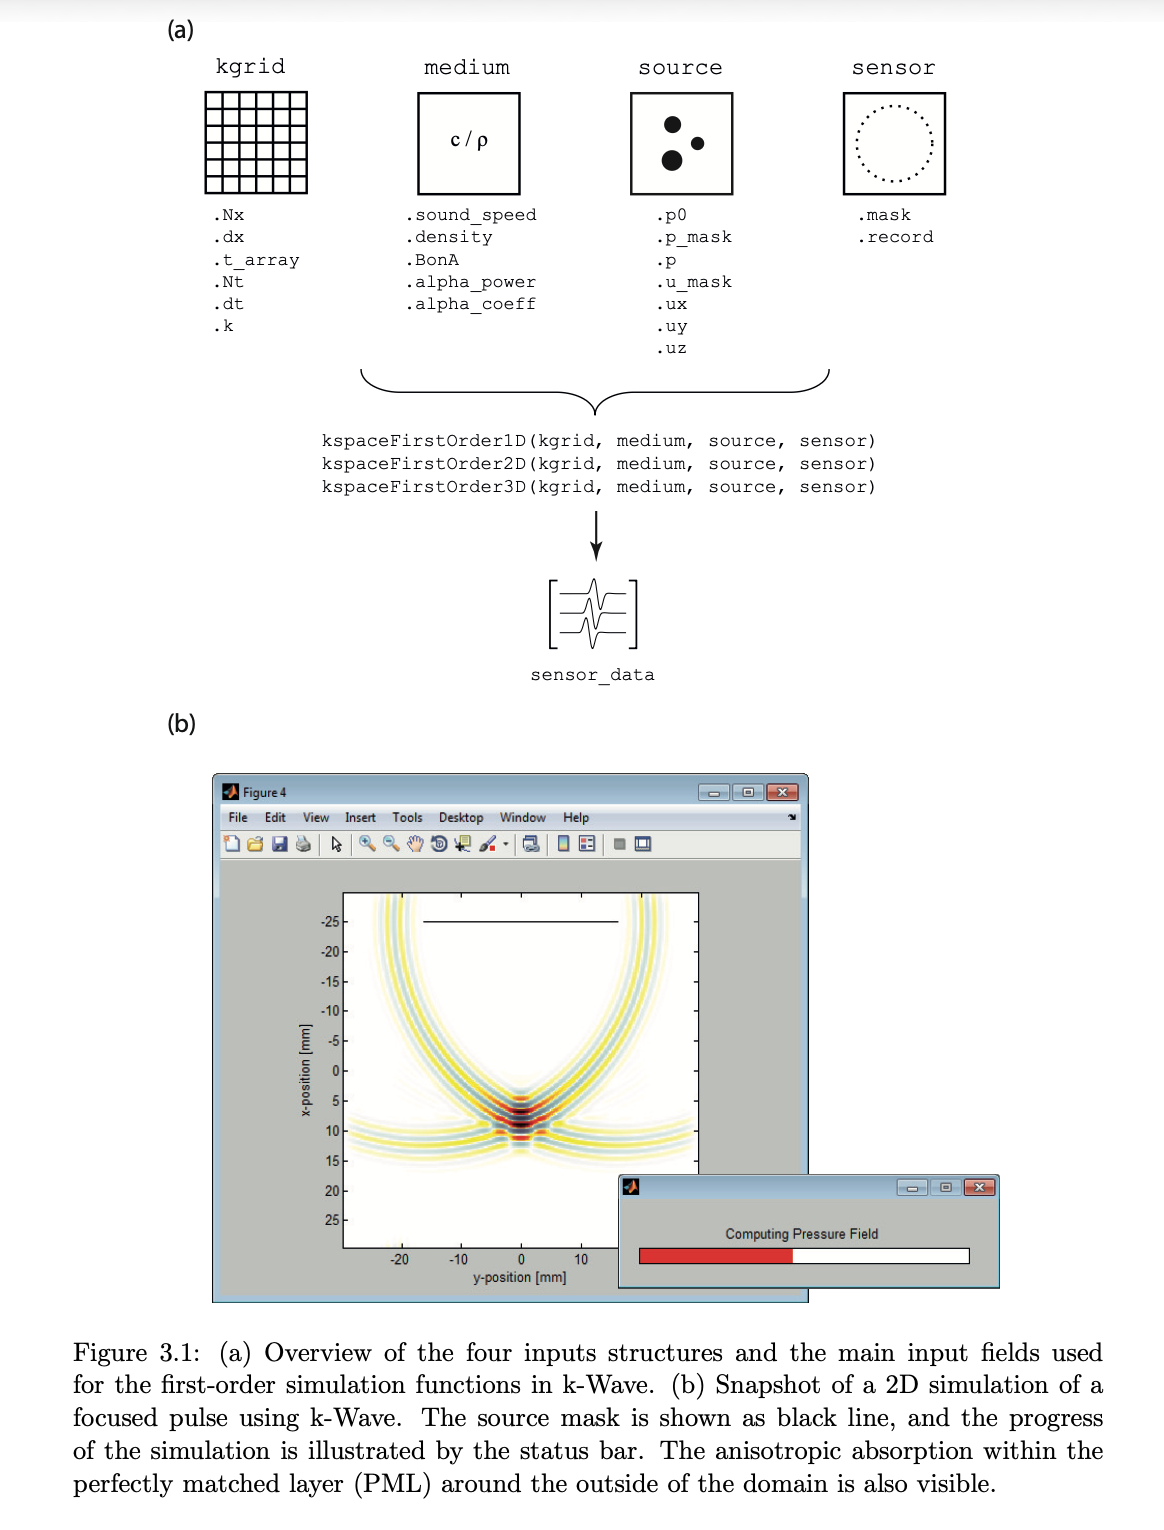

En resumen:

- `kgrid`: define **dónde y con qué resolución** se simula. O sea, tamaño de la malla, separación entre puntos y discretización espacial. 

- `medium`: define **por qué medio viaja la onda**, por ejemplo velocidad del sonido y densidad. 

- `source`: define **dónde y cómo se genera la onda.**

- `sensor`: define **dónde se mide la onda** mientras se propaga.

### **Kgrid**

Se puede generar la malla computacional 1D, 2D y 3D:

%(Nx, Ny, and Nz): numero de puntos de la malla
%(dx, dy, and dz): numero de espacio entre puntos de la malla

% create computational grid for a 1D simulation
%kgrid1 = makeGrid(Nx, dx);

% create computational grid for a 2D simulation
%kgrid2 = makeGrid(Nx, dx, Ny, dy);

% create computational grid for a 3D simulation
%kgrid3 = makeGrid(Nx, dx, Ny, dy, Nz, dz);

Se puede elegir Nx y dx calculados a partir de lo que quiero fisicamente simular con su frequencia maxima (f_max), velocidad minima del sonido del medio (c0_min), numero de puntos por malla y el tamano de lo que se quiere simular.

% Velocidad mínima del sonido en el medio [m/s]
c0_min = 1500;

% Frecuencia máxima que quieres representar correctamente [Hz]
f_max = 1e6;

% Número de puntos de malla por longitud de onda (esto puede aumentar el
% coste computacional)
points_per_wavelength = 3;

% Tamaño físico que quieres simular en x [m]
x_size = 50e-3;

% Tamaño físico que quieres simular en y [m]
y_size = 50e-3;

% compute dx and Nx based on a desired x_size and f_max
points_per_wavelength = 3;
dx = c0_min/(points_per_wavelength*f_max)

dx = 5.0000e-04

Nx = round(x_size/dx)

Nx = 100

Sin embargo, para simulaciones en medios homogeneos el limite teorico por Nyquist seria 2 puntos/λ, sin embargo se recomienda 3 por lo menos y 4 a mas para medios heterogeneos.

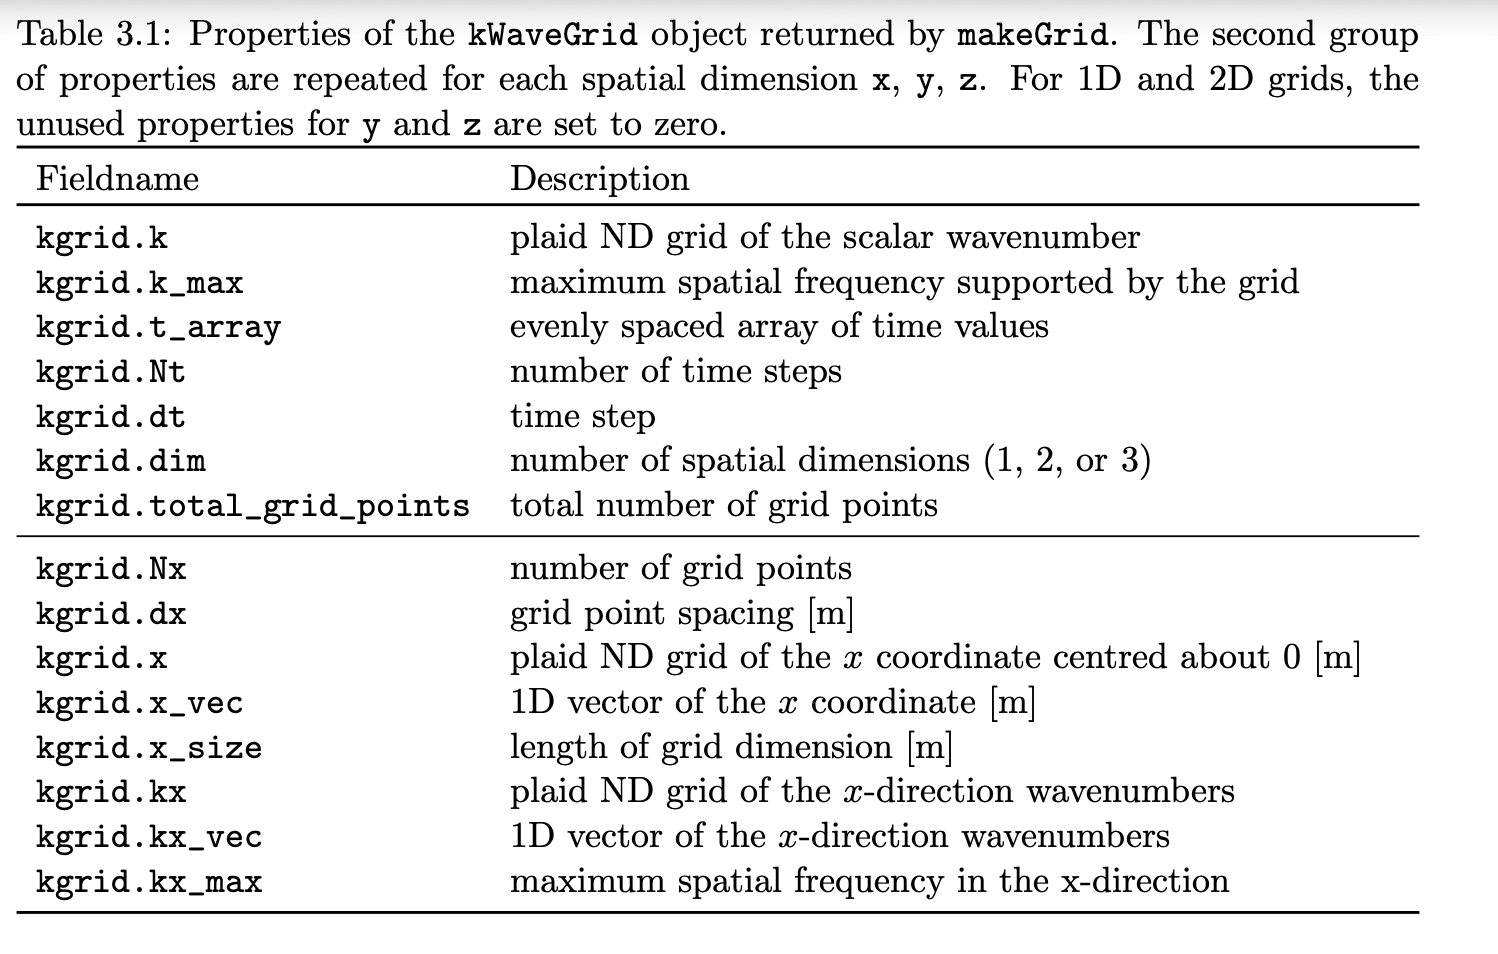

Asimismo, k-Wave usa muchas FFT en cada paso temporal. El manual dice que puede llegar a calcular **hasta 14 FFT por cada **`time step`, así que el tamaño de la matriz importa mucho para el tiempo de cómputo.

La FFT funciona especialmente rápido cuando el número de puntos de la malla tiene factores primos pequeños, por ello la idea es buscar cálculos físicos con valores mas cercanos a esos, por ello existe la funcion **checkFactors**.

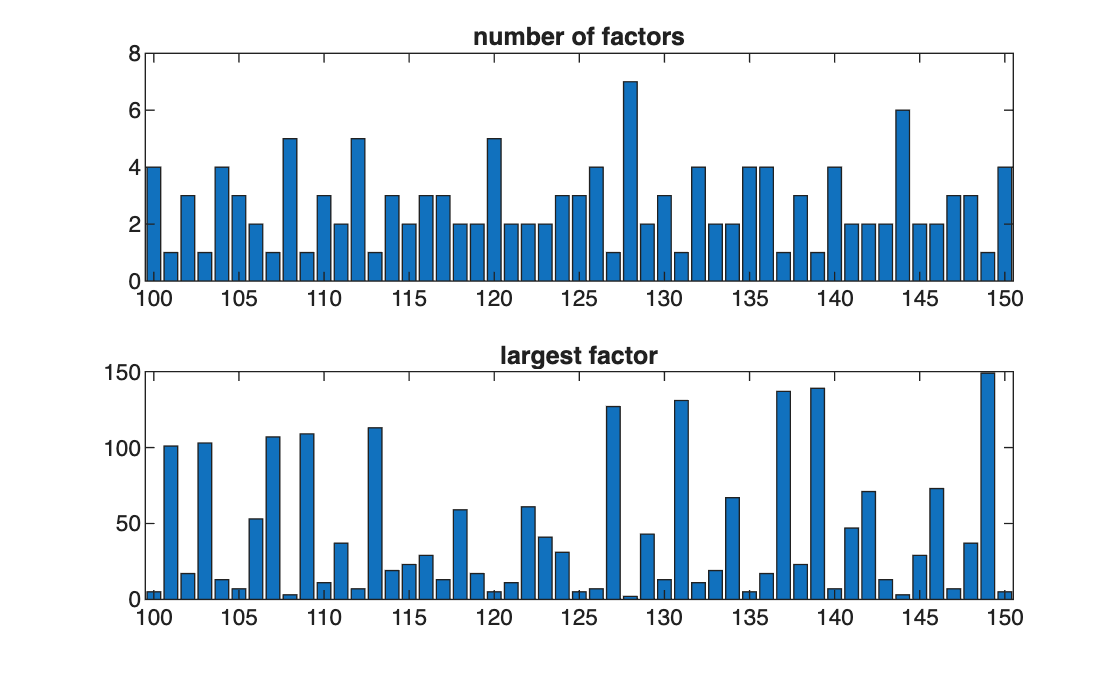

Numbers with a maximum prime factor of 2
128
Numbers with a maximum prime factor of 3
108  144
Numbers with a maximum prime factor of 5
100  120  125  135  150
Numbers with a maximum prime factor of 7
105  112  126  140  147
Numbers to avoid (prime numbers)
101  103  107  109  113  127  131  137  139  149


%Ejemplo para este grid (el numero tambien debe contar el PML)
checkFactors(100, 150)

Por ejemplo de aqui reviso que esta bien realmente escojer 100 y 150, pero 108 y 144 puede ser mas rapido por ejemplo, ya depende del caso de uso y las limitaciones.

Ademas, **cada cuánto tiempo calcula k-Wave el siguiente estado de la onda **es alterable:

% create the time array using makeTime setting the CFL and end time: defino todas las variables
kgrid.t_array = makeTime(kgrid, medium.sound_speed, CFL, t_end);

% create the time array using makeTime setting the end time: define automaticamente CFL y cambio t de duraicon yo. 
kgrid.t_array = makeTime(kgrid, medium.sound_speed, [], t_end);

% create the time array explicitly: defino manualmente el array de tiempo
kgrid.t_array = 0:1e-9:1e-6;

### Medium